clear; clc; close all; warning off;
syms x1 x2 x3 x4 u

%% Parámetros del sistema
ma = 0.6;        % masa brazo [kg]
mp = 0.2;        % masa péndulo [kg]
la = 1.1600e-1;  % largo brazo [m]
lp = 3.0001e-1;  % largo péndulo [m]
j0 = (ma * la^2) / 3; % inercia brazo
j1 = (mp * lp^2) / 3; % inercia péndulo
g = 9.8;             % gravedad [m/s^2]

% Parámetros auxiliares
a1 = ((ma + mp) / 3) * la^2;
a2 = j1;
a3 = (mp * la * lp) / 2;
a4 = (mp * g * lp) / 2;

%% Linealización del sistema para el controlador de estabilización
den = ((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);

f1 = x2;
f2 = ((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
      (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
      (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3 = x4;
f4 = ((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
      (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
      (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
      (a3*cos(x3)*u))/den;

f = [f1; f2; f3; f4];

A_sym = jacobian(f, [x1; x2; x3; x4]);
B_sym = jacobian(f, u);

% --- CORRECCIÓN 4: Punto de equilibrio para estabilización ---
% Se debe linealizar alrededor de la posición invertida (theta=0), que es
% el objetivo de la estabilización.
ref = 0; % Posición deseada del brazo
x_eq = [ref; 0; 0; 0]; % Estado de equilibrio (péndulo hacia arriba)
u_eq = (3*g*la*mp*sin(2*ref))/8; % Torque de equilibrio en la posición vertical es cero

% Sustitución en el punto de equilibrio correcto
A = double(subs(A_sym, [x1, x2, x3, x4, u], [x_eq.', u_eq]));
B = double(subs(B_sym, [x1, x2, x3, x4, u], [x_eq.', u_eq]));

% Diseño del controlador con integrador (para seguimiento de referencia)
C = [1 0 0 0];  % Salida: ángulo del brazo
Aa = [A, zeros(4,1); -C, 0];
Ba = [B; 0];

% --- DISEÑO DE CONTROLADOR LQR PARA MEJORAR RENDIMIENTO ---
% Se usa LQR en lugar de acker para tener control sobre la importancia de cada estado.

% Matriz de ponderación de estados Q (diagonal)
% [phi, dphi, theta, dtheta, error_integral_phi]
% --- DISEÑO DE CONTROLADOR LQR (AJUSTE FINO) ---
% Ponderaciones balanceadas para priorizar la estabilidad del péndulo
% sin descuidar el control del brazo.

% --- DISEÑO DE CONTROLADOR LQR (AJUSTE PARA SUAVIDAD) ---
Q = diag([1, 0.01, 3, 0.01, 10]);
R = 10; % Empezamos con un valor de R alto para un control suave

Ka = lqr(Aa, Ba, Q, R);
disp('Ganancias LQR (Ka):')

Ganancias LQR (Ka):


disp(Ka)

   -0.7462   -0.2284   -3.9085   -0.5286    1.0000




%% Parámetros del controlador Swing-up
params.mp = mp;
params.lp = lp;
params.g = g;
params.k = 2.0; % Ganancia del controlador de energía (se puede ajustar)
%% Simulación
Tsim = 60;   % Tiempo de simulación
Ts = 0.01;   % Período de muestreo
Ns = round(Tsim/Ts);
time = (0:Ns-1)' * Ts;

% Condición inicial: péndulo colgando casi verticalmente hacia abajo
x0 = [0; 0; pi; 0];
x_actual = x0;
x_hist = zeros(Ns, 4);
usim = zeros(Ns, 1);
ref_hist = zeros(Ns, 1);
e_hist = zeros(Ns, 1);
int_err = 0;
ref = 0; % Referencia para el ángulo del brazo

% Asegúrate de que complex_rot_pend.m esté en la misma carpeta o en el path de MATLAB
disp('Iniciando simulación con ODE45...');

Iniciando simulación con ODE45...



% Bucle de simulación
for i = 1:Ns
    theta = wrapToPi(x_actual(3));
    theta_dot = x_actual(4); % Necesitamos la velocidad para la nueva condición
    if i*Ts >5
        ref = 60*pi/180;
    end
    if i*Ts >10
        ref = 90*pi/180;
    end
    if i*Ts >15
        ref = 120*pi/180;
    end
    if i*Ts >20
        ref = 160*pi/180;
    end
    if i*Ts >25
        ref = 210*pi/180;
    end
    if i*Ts >30
        ref = 250*pi/180;
    end
    if i*Ts >35
        ref = 290*pi/180;
    end
    if i*Ts >40
        ref = 340*pi/180;
    end
    if i*Ts >45
        ref = 380*pi/180;
    end
    if i*Ts >50
        ref = 410*pi/180;
    end
    if i*Ts >55
        ref = 440*pi/180;
    end


    % Criterio de conmutación mejorado, basado en el paper 
   if abs(theta) < deg2rad(30) && abs(theta_dot) < deg2rad(50)
       %disp("Control")
        % MODO ESTABILIZACIÓN: Controlador lineal con integrador
         e = ref - x_actual(1);
         int_err = int_err + e * Ts;
         x_control = [x_actual; int_err];
        u_ctrl = -Ka * x_control;
   else
        %disp("Subir")
        % MODO SWING-UP: Controlador de energía
        u_ctrl = swing_up_energy_controller(x_actual, params);
        %u_ctrl = 0.15*cos(i*0.3);a
        int_err = 0; % Resetear el integrador
    end

    % Limitar la señal de control (opcional pero recomendado)
    u_max = 1;
    u_ctrl = max(min(u_ctrl, u_max), -u_max);

    % --- INTEGRACIÓN CON LA FUNCIÓN PROPORCIONADA ---
    % Se usa ode45 para simular el sistema durante un intervalo Ts
    % La función anónima @(t, x_state) permite pasar el control u_ctrl
    % a la función complex_rot_pend.
    [~, xd] = ode45(@(t, x_state) complex_rot_pend(t, x_state, [], u_ctrl), [0 Ts], x_actual);

    % El estado actual para la siguiente iteración es el último punto de la simulación
    x_actual = xd(end, :)';
    refh(i) = ref; 
    % Guardar datos históricos
    x_hist(i,:) = x_actual';
    usim(i) = u_ctrl;
    ref_hist(i) = ref;
    e_hist(i) = ref - x_actual(1);
end
disp('Simulación completada.');

Simulación completada.


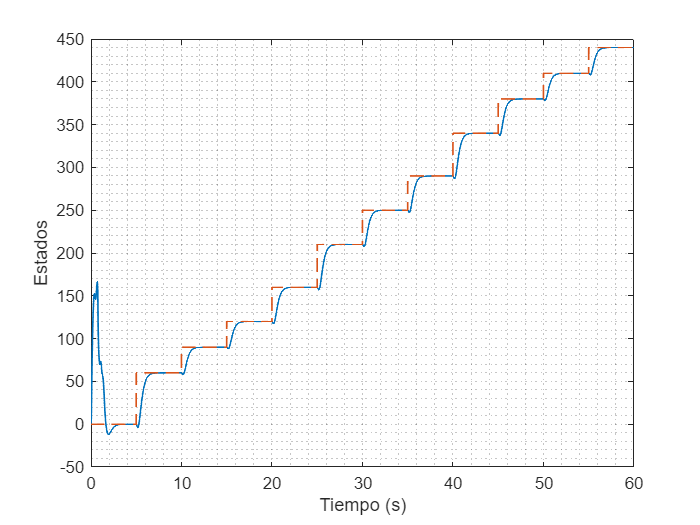

figure;
plot(time, x_hist(:, 1)*180/pi, LineWidth=1)
hold on 
plot(time, refh*180/pi,'--', LineWidth=1)
grid minor;
xlabel('Tiempo (s)');
ylabel('Estados');

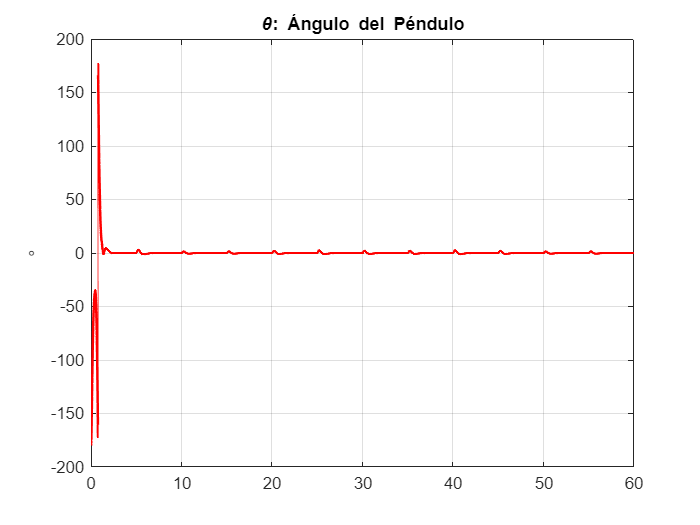

figure;
legend('Posición Brazo (x1)', 'Referencia');
plot(time, rad2deg(wrapToPi(x_hist(:,3))), 'r', 'LineWidth', 1.5);
title('\theta: Ángulo del Péndulo'); ylabel('°'); grid on;

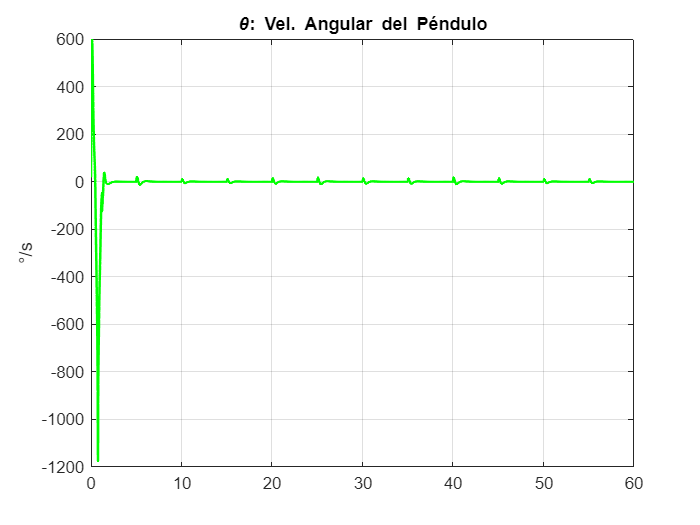

%ylim([-200, 200]);

plot(time, rad2deg(x_hist(:,4)), 'g', 'LineWidth', 1.5);
title('\theta: Vel. Angular del Péndulo'); ylabel('°/s'); grid on;

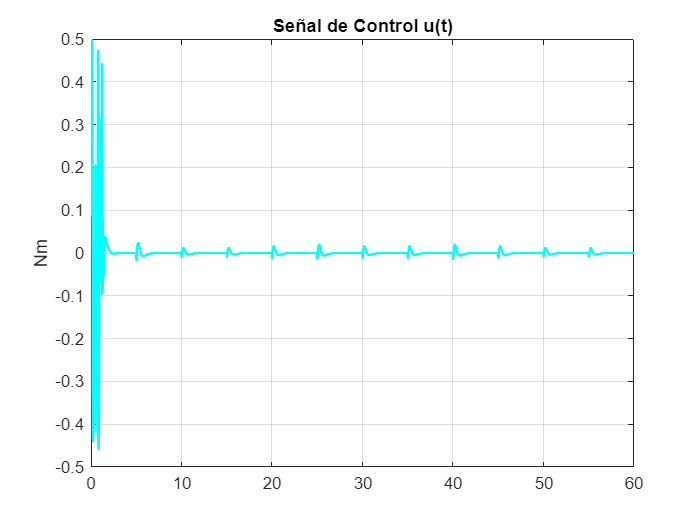


plot(time, usim, 'c', 'LineWidth', 1.5);
title('Señal de Control u(t)'); ylabel('Nm'); grid on;

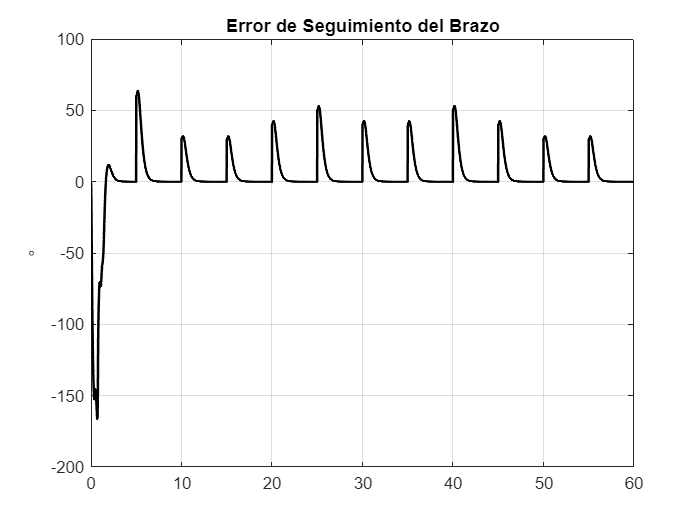


plot(time, rad2deg(e_hist), 'k', 'LineWidth', 1.5);
title('Error de Seguimiento del Brazo'); ylabel('°'); grid on;

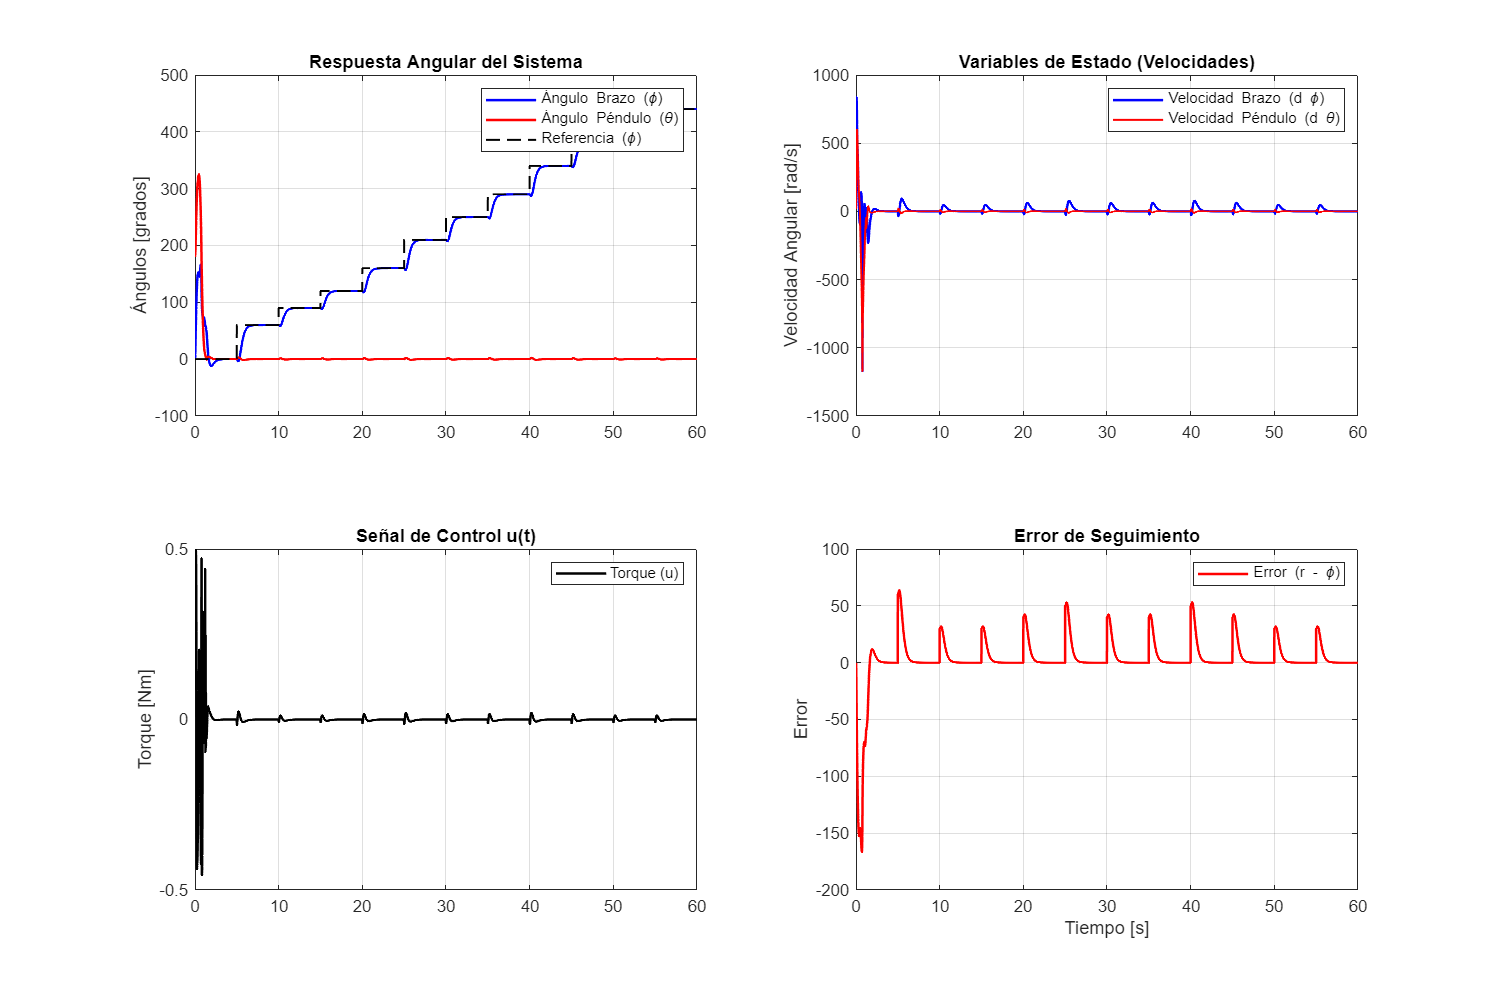

% Gráficas en subplot 2x2
figure;
set(gcf, 'Position', [100, 100, 800, 600]); % Tamaño de la figura

figure('Position', [100, 100, 1200, 800]);

subplot(2,2,1)
plot(time, x_hist(:,1)*180/pi, 'blue', 'LineWidth', 1.5) % x1: Ángulo del brazo
hold on
plot(time, x_hist(:,3)*180/pi, 'red', 'LineWidth', 1.5);   % x3: Ángulo del péndulo
plot(time, refh*180/pi, 'black--', 'LineWidth', 1.2);
ylabel('Ángulos [grados]')
legend('Ángulo Brazo (\phi)', 'Ángulo Péndulo (\theta)', 'Referencia (\phi)');
title('Respuesta Angular del Sistema')
grid on

subplot(2,2,2)
plot(time, x_hist(:,2)*180/pi, 'blue', 'LineWidth', 1.5); % x2: Vel. angular brazo
hold on
plot(time, x_hist(:,4)*180/pi, 'red', 'LineWidth', 1.2);   % x4: Vel. angular péndulo
ylabel('Velocidad Angular [rad/s]')
legend('Velocidad Brazo (d \phi)', 'Velocidad Péndulo (d \theta)');
title('Variables de Estado (Velocidades)')
grid on

subplot(2,2,3)
plot(time, usim, 'k', 'LineWidth', 1.5)
ylabel('Torque [Nm]')
legend('Torque (u)');
title('Señal de Control u(t)')
grid on

subplot(2,2,4)
plot(time, e_hist*180/pi, 'r', 'LineWidth', 1.5)
xlabel('Tiempo [s]')
ylabel('Error')
legend('Error (r - \phi)');
title('Error de Seguimiento')
grid on

set(gcf, 'Color', 'w');


% Cálculo de ITAE y energía
ITAE = trapz(time, time .* abs(e_hist)) * Ts; % Integral del tiempo por error absoluto
Energy = trapz(time, usim.^2) * Ts; % Energía de la señal de control
fprintf('ITAE: %.4f\n', ITAE);

ITAE: 1.6702


fprintf('Energía: %.4f\n', Energy);

Energía: 0.0011
